# Run a quality analysis using only MSX functions

THE USER HAS TO ADD api to call THE MSX FUNCTIONS e.g., apiMSXsolveH

## Clear - Start Toolkit

clear; close('all'); clc;
start_toolkit;

EPANET-MATLAB Toolkit Paths Loaded.


## Create EPANET object using the INP file

inpname='net2-cl2.inp'; %net2-cl2 example
d = epanet(inpname);

EPANET version {20200} loaded (EMT version {v2.2.1}).
Loading File "net2-cl2.inp"...
Input File "net2-cl2.inp" loaded successfully.


msxname = [inpname(1:end-4),'.msx'];
d.apiMSXMatlabSetup(msxname);        
ss=1:d.LinkCount;%index link
uu=1:d.MSXSpeciesCount;
value.Quality = cell(1, length(ss));

## Obtain a hydraulic solution

d.apiMSXsolveH(d.MSXLibEPANET);

## Run a step-wise water quality analysis without saving RESULTS to file

d.apiMSXinit(0, d.MSXLibEPANET);

## Retrieve species concentration at node

k = 1; tleft = 1;
time_step = 360;
value.Time(k, :)=0;
while(tleft>0)
    [Errcode, t, tleft]= d.apiMSXstep(d.MSXLibEPANET);
    if Errcode, obj.apiMSXerror(Errcode, obj.MSXLibEPANET); end
    if t <= time_step
        i=1;
        for nl=ss
            g=1;
            for j=uu
                % MSX_Link = 1
                % Initialise the quality values of links
                [d.Errcode, value.Quality{i}(j)] = d.apiMSXgetinitqual(1, i, j, d.MSXLibEPANET);
            end
            i=i+1;
        end
    else
        i=1;
        for nl=ss
            g=1;
            for j=uu
                 % MSX_LINK = 1
                 % Change the quality values of the links
                 [Errcode, value.Quality{i}(k, g)] = d.apiMSXgetqual(1, (nl), j, d.MSXLibEPANET);
                g=g+1;
            end
            i=i+1;
        end
    end
    value.Time(k, :)=t;
    k = k + 1;
end

## Plot quality over time (in hrs) for link 1

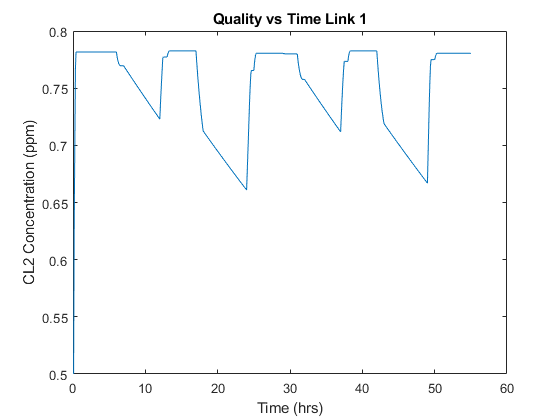

figure
plot(value.Time/3600,value.Quality{1})
title('Quality vs Time Link 1')
xlabel('Time (hrs)')
ylabel('CL2 Concentration (ppm)')

## Plot quality over time (in hrs) for link 36 

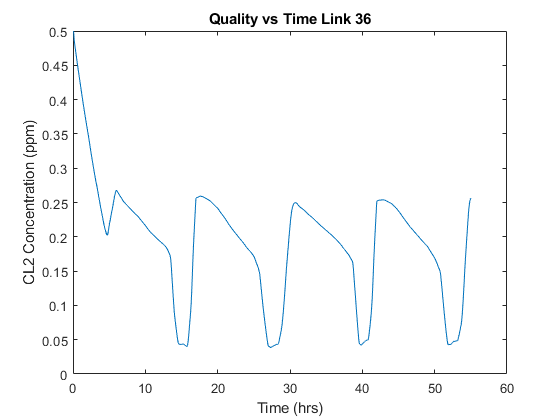

figure
plot(value.Time/3600,value.Quality{36})
title('Quality vs Time Link 36')
xlabel('Time (hrs)')
ylabel('CL2 Concentration (ppm)')

## Unload MSX library and EN library.

d.apiMSXclose(d);
d.apiMSXMatlabCleanup(d);
fclose('all');
disp('MSX unloaded');

MSX unloaded



d.unload;

EPANET Class is unloaded
